# Getting the auto/cross covariance function from data

## Introduction

In this tutorial you will learn how to estimate the auto/cross covariance function of a random process from a time series. The time series is assumed to be a realisation of a zero-mean random process. The autocovariance function is a discrete function that depends on the lag $m$, $\gamma_{ii}[m]$. The cross covariance function between variables $i$ and $j$ of a multivariate time series is $\gamma_{ij}[m]$.

The dataset employed in this tutorial is '*database/case_02_VAR_2V*', which includes a synthetic time series of the multivariate autoregressive (VAR) model, and the related true Covariance Matrix Function (GammaMV). This allows comparison between the estimated and the true auto/cross covariance functions. 

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters

method  = 'unbiased_matlab'; % Estimation method:
                             %   'unbiased' (estimated with mVARbox function) 
                             %   'biased' (estimated with mVARbox function)
                             %   'unbiased_matlab' (estimated with matlab native 
							 %					   function 'xcov')
                             %   'biased_matlab' (estimated with matlab native 
							 %					 function 'xcov')
                             % See function 'initialise_gamma' for details.
                             % Leave empty [] for default value set by function 
                             % 'fun_default_value'.

M       = 100;  % máximum lag considered for gamma estimation

k_index = 1;    % Time series from data to be considered.
                %   k_index = 1 for autocovariance of y1 (first data column)
                %   k_index = 2 for autocovariance of y2 (second data column)
                %   k_index = [1 2] for cross covariance between y1 and y2
                %   k_index = [2 1] for cross covariance between y2 and y1
                % If not provided, default value is taken from function 
                % 'fun_default_value'.


%%% Plot parameters
font_size       = 18;
figure_position = [0 0 1000 400];
CC              = colororder;
color_estimated = CC(3,:);
color_true      = CC(4,:);

Load the dataset. It consists of two objects, one in the form of a `data` object, and one in the form of a GammaMV object. For details related to the fields of these objects, see functions `initialise_data` and `initialise_GammaMV`.

load case_02_VAR_2V.mat data_VAR GammaMV_VAR

Have a look at the time series considered. 

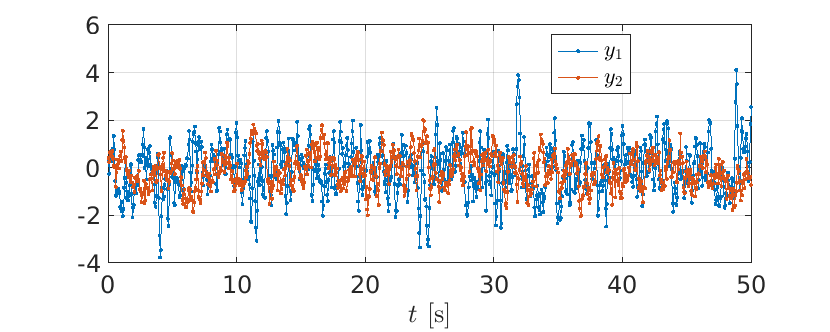

figure

x = data_VAR.x_values;
y = data_VAR.y_values;
plot(x,y,'.-')

grid on
legend({'$y_1$','$y_2$'},...
        'Interpreter','latex',...
        'Location','best')
xlabel('$t$ [s]','Interpreter','latex')
xlim([0 data_VAR.x_values(end)])

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

Initialise a `gamma_fun` object with the fields required by function `get_gamma_data`.

[gamma_fun] = initialise_gamma('method', method, 'M', M);

Compute the auto/cross covariance, according to parameter `k_index`.

[gamma_fun] = get_gamma_data(data_VAR, gamma_fun, k_index);

Plot the obtained covariance function in time domain, together with the true covariance function.

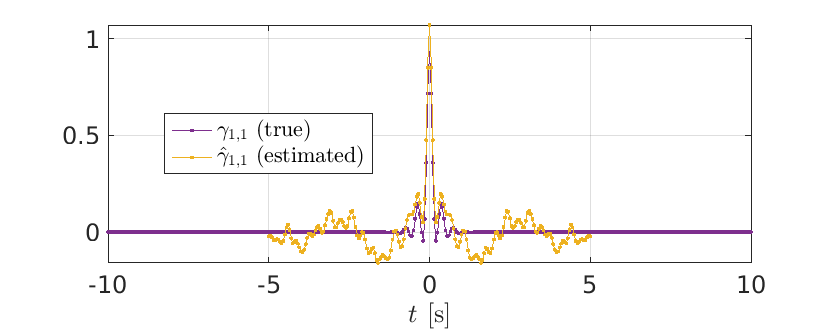

figure

% handle dimension of k_index through k_vector
if size(k_index)==1
    k_vector = [k_index k_index];
else
    k_vector = k_index;
end

% plots
x = GammaMV_VAR.x_values;
y = squeeze(GammaMV_VAR.y_values(k_vector(1),k_vector(2),:));
plot(x,y,'.-','Color',color_true)

hold on

x = gamma_fun.x_values;
y = gamma_fun.y_values;
plot(x,y,'.-','Color',color_estimated)

grid on
leg_true = sprintf('$\\gamma_{%d,%d}$ (true)',k_vector(1),k_vector(2));
leg_est  = sprintf('$\\hat{\\gamma}_{%d,%d}$ (estimated)',k_vector(1),k_vector(2));
legend({leg_true , leg_est},...
        'Interpreter','latex',...
        'Location','best')
xlabel('$t$ [s]','Interpreter','latex')

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

Note that the true and the estimated covariance functions may have different time spans. Plot the obtained covariance function in lag domain, together with the true covariance function, and limit the plot to lag 50.

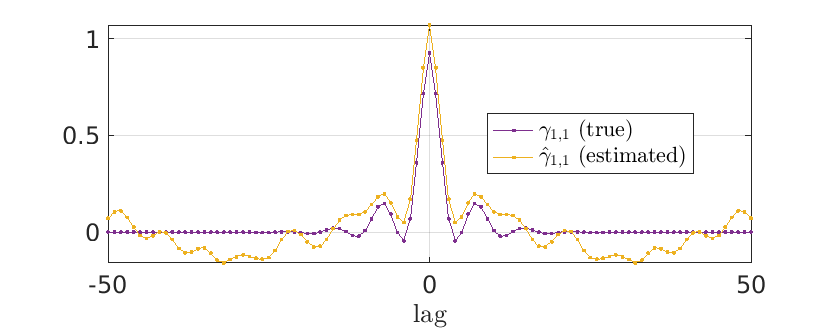

figure

x = GammaMV_VAR.xlag_values;
y = squeeze(GammaMV_VAR.y_values(k_vector(1),k_vector(2),:));
plot(x,y,'.-','Color',color_true)

hold on

x = gamma_fun.xlag_values;
y = gamma_fun.y_values;
plot(x,y,'.-','Color',color_estimated)

grid on
xlim([-50 50])
legend({leg_true , leg_est},...
        'Interpreter','latex',...
        'Location','best')
xlabel('lag','Interpreter','latex')

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

## Remarks

- You can check that the autocovariance function, $\gamma_{ii}[k]$, is always symmetric. However, this is not necessarily the case for the cross covariance function ( $\gamma_{ij}$ , with $i \neq j$). Also, you can check that $\gamma_{ij}[m] = \gamma_{ji}[-m]$.

- While biased and unbiased methods provide very similar results for small lag values, the variance of the unbiased estimator increases greatly for very large lag values. You can check this by computing the unbiased approach for `M `values around 80-90% of the data length.

- An error pops up if the covariance function is estimated for a lag equal or larger than the data size (`M`$\geq$`data_VAR.x_parameters.N`).